# Solución de ecuaciones diferenciales de orden superior

Un métodopara resolver ecuaciones diferenciales de orden superior es el de coeficientes indeterminados. Por ejemplo:


$${y}''+p(t){y}'+1(t)y=g(t)$$


La principal ventaje de este método es que  reduce el problema a uno de tipo algebraico. Mientras que su principal desventaja es que solo se puede utilizar para $g(t)$ simples.

Ahora, para el caso de ecuaciones no-homogéneas, se debe obtener una solución general ($y_c(t)$) tomando la expresión como homogénea y otra particular ($y_p(t)$)  para el caso de $g(t)$. Donde la solución de la expresión no homogénea será la suma de ambas soluciones ($y(t)= y_c(t)+y_p(t)$).

Algunas funciones básica para $g(t)$:

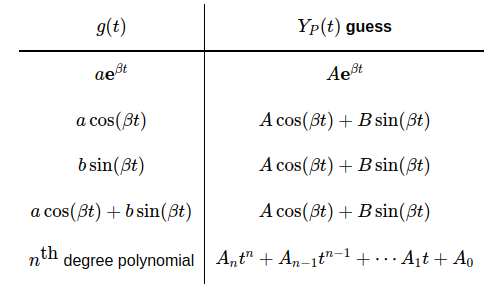

**Tabla 1. **Obtenida de [[1]](https://tutorial.math.lamar.edu/classes/de/undeterminedcoefficients.aspx)

**1.** Solución a ecuación homogénea ${y}'' + 3{y}' + 2{y} = 0$ con

 
$$y(0)=0\\
{y}'(0)=0\\
{y}''(0)=1$$


**Solución analítica: **


$$\begin{array}{rcl}
\lambda^2e^{\lambda t}+3\lambda e^{\lambda t} + 2e^{\lambda t}&=&0\\
e^{\lambda t}(\lambda+2)(\lambda+1)&=&0
\end{array}$$


con $\lambda=-1$ y $\lambda=-2$ tenemos que la solución es 


$$y = c_1e^{-t} + c_2e^{-2t}$$


syms y(t)
Dy2 = diff(y,t,2);
Dy = diff(y,t,1);
eq1 = Dy2 + 3*Dy + 2*y == 0;
dsolve(eq1);
CI1 = y(0)==0; CI2 = Dy(0)==1;
Sol = dsolve(eq1,[CI1,CI2])

$$Sol = {\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t}$$

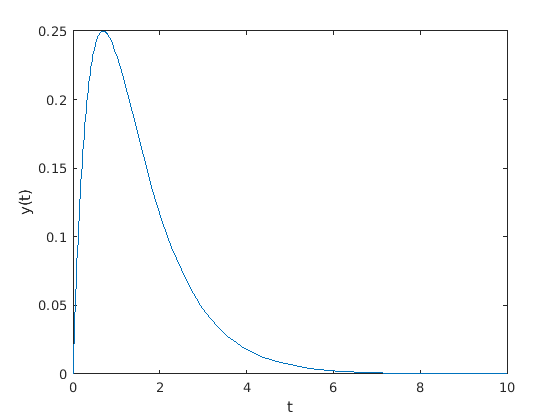

fplot(Sol,[0 10])
xlabel('t')
ylabel('y(t)')

**2. **Solución a ecuación no-homogénea ${y}'' + 3{y}' + 2{y} = t+1$ con

 
$$y(0)=0\\
{y}'(0)=1\\$$


**Solución analítica:**

Por ejercicio anterior sabemos que $y = c_1e^{-t} + c_2e^{-2t}$ 

Ahora, vamos a obtener la solución particular $y_p(t)$:


$$\begin{array}{rcl}
y_p&=&at+b\\[5pt]
y^{'}_p&=&a\\[5pt]
y^{''}_p&=&0\\[5pt]
{y}''_p + 3{y}'_p + 2{y}_p&=&0+3a+2(at+b)
\end{array}$$


Luego, para despejar $a$ y $b$ utilizamos la igualdad $0+3a+2(at+b) = t+1$


$$\begin{array}{rcl}
3a+2b &=& 1\\
2at &=& t
\end{array}$$


Con lo cual $a=1/2$ y $b=-1/4$


$$y_p=1/2t-1/4$$


 
$$\begin{array}{rcl}
y &=& y_c + y_p\\
  &=& c_1e^{-t} + c_2e^{-2t} + \frac{1}{2}t - \frac{1}{4}
\end{array}$$
       

syms y(t)
Dy2 = diff(y,t,2);
Dy = diff(y,t,1);
eq2 = Dy2 + 3*Dy + 2*y == t+1;
dsolve(eq2);
CI1 = y(0)==0; CI2 = Dy(0)==0;
Sol = dsolve(eq2,[CI1,CI2])

$$Sol = \frac{t}{2}+\frac{{\mathrm{e}}^{-2\,t}}{4}-\frac{1}{4}$$

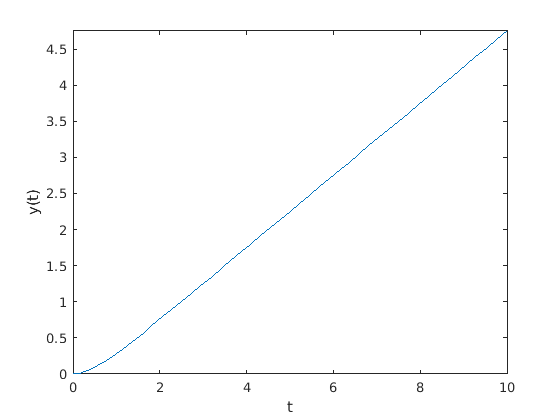

fplot(Sol,[0 10])
xlabel('t')
ylabel('y(t)')

**3. **Solución a ecuación no-homogénea ${y}'' + 3{y}' + 2{y} =e^{-t}$ con

 
$$y(0)=0\\
{y}'(0)=1\\$$


**Solución analítica:**

Por ejercicio anterior sabemos que $y = c_1e^{-t} + c_2e^{-2t}$ 

Ahora, vamos a obtener la solución particular $y_p(t)$:


$$\begin{array}{rcl}
y_p&=&ate^{-t}\\[5pt]
y^{'}_p&=&-a(t-1)e^{-t}\\[5pt]
y^{''}_p&=&a(t-2)e^{-t}\\[5pt]
{y}''_p + 3{y}'_p + 2{y}_p&=&a(t-2)e^{-t}-3a(t-1)e^{-t}+2ate^{-t}
\end{array}$$


 Luego, para despejar $a$ y $b$ utilizamos la igualdad $a(t-2)e^{-t}-3a(t-1)e^{-t}+2ate^{-t}= e^{-t}$


$$\begin{array}{rcl}
ate^{-t} &=& te^{-t}\\
a &=& 1
\end{array}$$


Con lo cual $y_p=e^{-t}$ :


$$y= c_1e^{-t} + c_2e^{-2t} +te^{-t}$$


syms y(t)
Dy2 = diff(y,t,2);
Dy = diff(y,t,1);
eq3 = Dy2 + 3*Dy + 2*y == exp(-t);
dsolve(eq3);

$$ans = t\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-t}+C_{1}\,{\mathrm{e}}^{-2\,t}+C_{2}\,{\mathrm{e}}^{-t}$$

CI1 = y(0)==0; CI2 = Dy(0)==0;
Sol = dsolve(eq3,[CI1,CI2])

$$Sol = {\mathrm{e}}^{-2\,t}\,\left(t\,{\mathrm{e}}^{t}-{\mathrm{e}}^{t}+1\right)$$

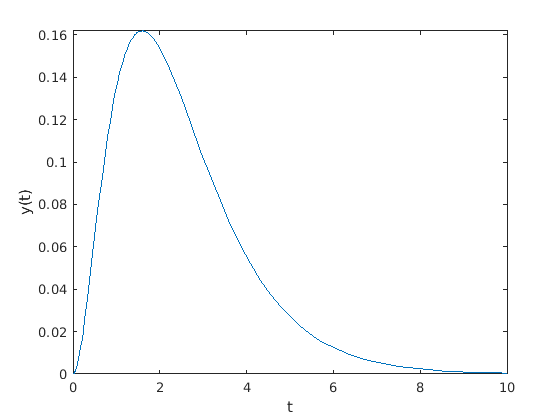

fplot(Sol,[0 10])
xlabel('t')
ylabel('y(t)')

**4. **Solución a ecuación homogénea ${y}'' + 4{y} = 0$ con

 
$$y(0)=1\\
{y}'(0)=0\\$$


**Solución analítica:**


$$\begin{array}{rcl}
\lambda^2e^{\lambda t} + 4 \lambda e^{\lambda t} &=& 0\\[5pt]
e^{\lambda t}(\lambda^2 + 4 \lambda) &=& 0
\end{array}


$$
 

 con $\lambda=-2i$ y $\lambda=2i$ tenemos que la solución es $y = c_1e^{-2ti}+c_2e^{2ti}$

Aplicando la igualdad de euler $e^{\alpha +i\beta} = e^{\alpha}\cos(\beta)+ie^{\beta}\sin(\beta)$:


$$\begin{array}{rcl}
y &=& c_1(\cos(2t)+i\sin(2t))+c_2(\cos(2t)-i\sin(2t))\\[15pt]
 &=& (c_1+c_2)\cos(2t)+ i (c_1-c_2)\sin(2t)\\[15pt]
 &=& C_1\cos(2t)+ C_2\sin(2t)\\[15pt]
\end{array}$$


syms y(t)
Dy2 = diff(y,t,2);
eq4 = Dy2 + 4*y == 0;
dsolve(eq4);
CI1 = y(0)==1; CI2 = Dy(0)==0;
Sol = dsolve(eq4,[CI1,CI2])

$$Sol = \cos\left(2\,t\right)$$

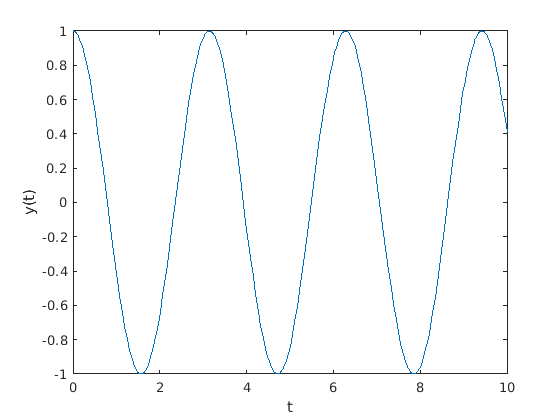

fplot(Sol,[0 10])
xlabel('t')
ylabel('y(t)')

**5. **Solución a ecuación homogénea ${y}'' + 4{y} = \sin(t)$ con

 
$$y(0)=1\\
{y}'(0)=0\\$$


Por ejercicio anterior sabemos que $y =C_1\cos(2t)+ C_2\sin(2t)$ 

Ahora, vamos a obtener la solución particular $y_p(t)$:


$$\begin{array}{rcl}
y_p&=&a\sin t +b \cos t\\[5pt]
y^{'}_p&=&a\cos t - b \sin t\\[5pt]
y^{''}_p&=&-a\sin t - b \cos t\\[5pt]
y^{''}_p+4y_p&=&-a\sin t - b \cos t+ 4(a\sin t +b \cos t)
\end{array}$$


 Luego, para despejar $a$ y $b$ utilizamos la igualdad $3a\sin t+3b\cos t = \sin(t)$


$$\begin{array}{rcl}
a &=& 1/3\\
b &=& 0
\end{array}$$


Con lo cual $y_p=\frac{1}{3}\sin t$ :


$$y= C_1\cos(2t)+ C_2\sin(2t) + \frac{1}{3}\sin t$$


syms y(t)
Dy2 = diff(y,t,2);
eq5 = Dy2 + 4*y == sin(t);
simplify(dsolve(eq5));
CI1 = y(0)==1; CI2 = Dy(0)==0;
Sol = simplify(dsolve(eq5,[CI1,CI2]))

$$Sol = 2\,{\cos\left(t\right)}^{2}-\frac{\sin\left(t\right)\,\cos\left(t\right)}{3}+\frac{\sin\left(t\right)}{3}-1$$

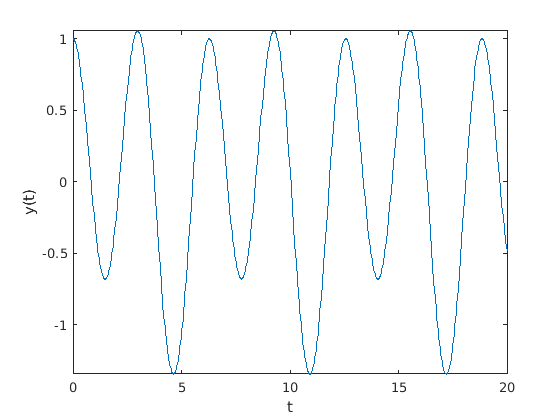

fplot(Sol,[0 20])
xlabel('t')
ylabel('y(t)')